parameter settings

clear all

nDelay = 3; %4 % # of delays
nDim = 3;

params.sigma = 10;
params.beta = 8/3;
params.rho = 28;
params.eta = sqrt(params.beta*(params.rho-1));

data generation

[t,x] = lorenzgen(params);

Visualize

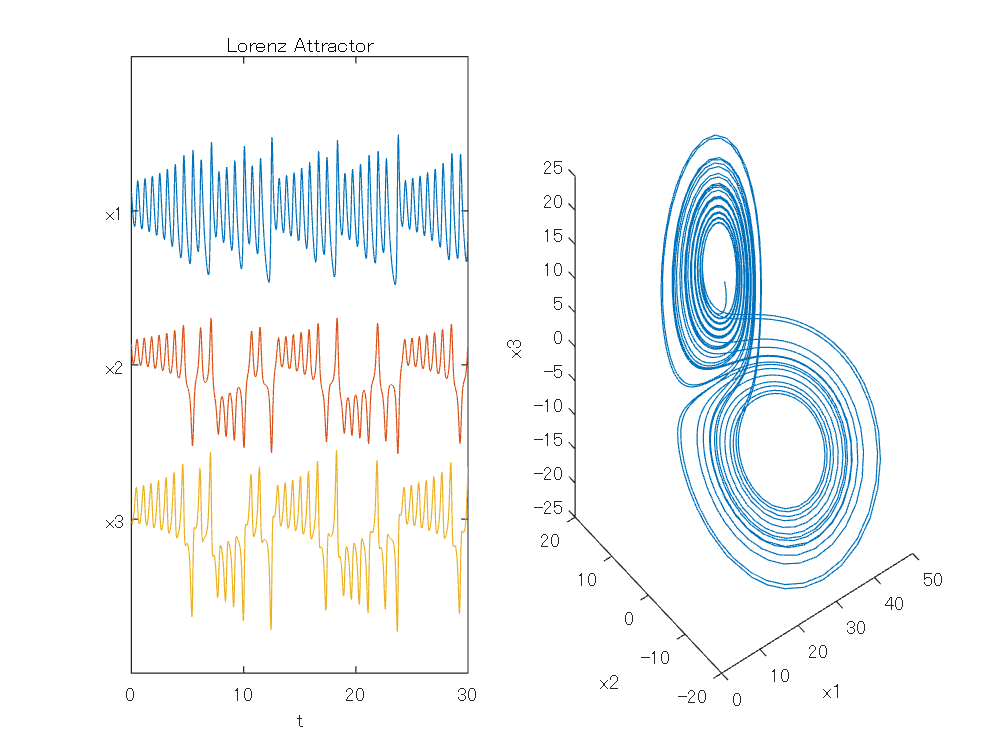

myplot(t,x);

Step 0 Preprocess w/ LSUN

Step 1 Delayed embedding and data matrix generation

ts = [];
H = [];
nRange = size(x,1)-1;
for k = 0:nRange-nDelay
    xkT = [];
    for iDelay = 0:nDelay
        xkT = cat(2,xkT,x(k+iDelay+1,:));
    end
    H = cat(2,H,xkT.');
end

H

H =    30.0000   29.6945   29.3613   29.0067   28.6359   27.7089   26.7620   25.8290   24.9334   23.9586   23.0771   22.3091   21.6779   21.2609   20.9852   20.8725   20.9471   21.2916   21.9493   22.9390   24.2483   25.6163   27.1179   28.6515   30.0961   31.3201   32.2138   32.7123   32.8015   32.4965   31.8533   30.9556   29.9082   28.9660   28.0021   27.0423   26.1055   25.0893   24.1341   23.2527   22.4572   21.6845   21.0556   20.5954   20.3352   20.3099   20.5633   21.1363   22.0585   23.1500
   10.4853    9.9720    9.4862    9.0287    8.6001    7.6915    6.9489    6.3676    5.9362    5.6025    5.4382    5.4299    5.5584    5.7682    6.0682    6.4540    6.9187    7.5354    8.2299    8.9765    9.7339   10.3639   10.9174   11.3471   11.6113   11.6777   11.5286   11.1686   10.6298    9.9197    9.1256    8.3112    7.5290    6.9201    6.3816    5.9237    5.5519    5.2357    5.0276    4.9237    4.9185    5.0221    5.2390    5.5669    6.0010    6.5363    7.1707    7.8933    8.6820    9

Step 2 SVD of H

[U,Sgm,V] = svd(H,'econ')

U =    -0.4958   -0.0659   -0.0172   -0.6685    0.0235    0.4381   -0.2395   -0.0338   -0.2040   -0.0723   -0.0694    0.0036
   -0.0440    0.3180   -0.4996   -0.0009   -0.0996   -0.2958   -0.5348    0.0308   -0.1153    0.4548   -0.0699   -0.1948
   -0.0430    0.3761    0.1208    0.0251    0.6957    0.0149   -0.0612    0.5338   -0.0798   -0.0133    0.2143    0.1270
   -0.4969   -0.0628   -0.0053   -0.2253    0.0244   -0.4304    0.2497    0.0366    0.6062    0.1884    0.2140   -0.0099
   -0.0440    0.3297   -0.3991    0.0068   -0.0665   -0.0796   -0.0948   -0.1343    0.2175   -0.5666   -0.1185    0.5567
   -0.0425    0.3739    0.2607    0.0066    0.3432   -0.0190   -0.0016   -0.4395    0.2138   -0.0796   -0.5294   -0.3832
   -0.4968   -0.0591    0.0104    0.2275    0.0013   -0.4308    0.2517    0.0197   -0.6095   -0.1648   -0.2229    0.0095
   -0.0439    0.3387   -0.2947    0.0086   -0.0988    0.1533    0.3025   -0.1201   -0.1035   -0.2994    0.5185   -0.5366
   -0.0418    0.3668    0.38

Sgm = 1.0e+03 *

    2.1627         0         0         0         0         0         0         0         0         0         0         0
         0    0.9095         0         0         0         0         0         0         0         0         0         0
         0         0    0.2610         0         0         0         0         0         0         0         0         0
         0         0         0    0.1162         0         0         0         0         0         0         0         0
         0         0         0         0    0.0689         0         0         0         0         0         0         0
         0         0         0         0         0    0.0116         0         0         0         0         0         0
         0         0         0         0         0         0    0.0105         0         0         0         0         0
         0         0         0         0         0         0         0    0.0078         0         0         0         0
         0     

V =    -0.0282    0.0132   -0.0309   -0.0057   -0.0323    0.0197    0.0366   -0.0197    0.0049    0.0029   -0.0154   -0.0058
   -0.0278    0.0123   -0.0291   -0.0062   -0.0312    0.0187    0.0337   -0.0191    0.0045    0.0022   -0.0145   -0.0057
   -0.0273    0.0114   -0.0269   -0.0097   -0.0279   -0.0174    0.0176   -0.0328   -0.0465   -0.1057    0.0615   -0.1471
   -0.0267    0.0105   -0.0242   -0.0143   -0.0251   -0.0373   -0.0207   -0.0269    0.0722   -0.0909    0.0163    0.1614
   -0.0259    0.0098   -0.0206   -0.0179   -0.0237   -0.0279   -0.0588   -0.0135   -0.0081    0.0289   -0.0076   -0.0128
   -0.0250    0.0092   -0.0162   -0.0179   -0.0230   -0.0217   -0.0515   -0.0127   -0.0078    0.0265   -0.0092   -0.0147
   -0.0241    0.0090   -0.0119   -0.0183   -0.0223   -0.0230   -0.0444   -0.0082   -0.0168    0.0058   -0.0106   -0.0414
   -0.0233    0.0092   -0.0079   -0.0185   -0.0220   -0.0188   -0.0412   -0.0045    0.0079    0.0167   -0.0003    0.0184
   -0.0225    0.0098   -0.00

Step 3 PCT

iMode = 1

iMode = 1

ui = reshape(U(:,iMode),size(x,2),[]).'

ui =    -0.4958   -0.0440   -0.0430
   -0.4969   -0.0440   -0.0425
   -0.4968   -0.0439   -0.0418
   -0.4957   -0.0436   -0.0411


Visualize

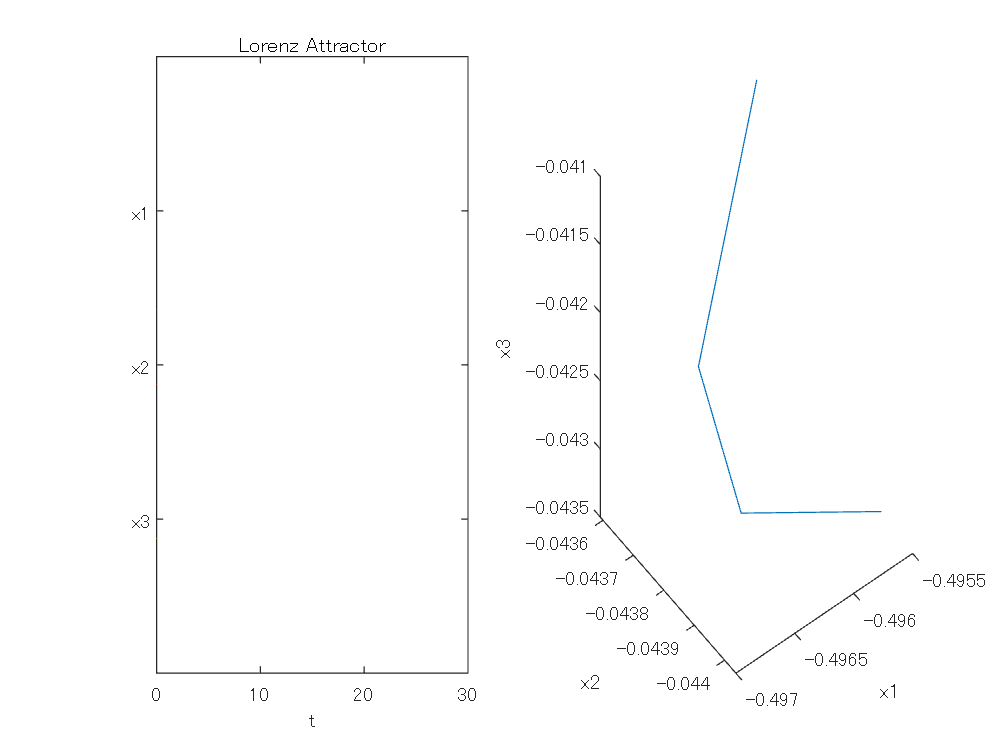

myplot(t(1:size(ui,1)),ui)

Step 3 Time step 

V0 = V(1:end-1,:);
V1 = V(2:end,:);
dtAplusI = (V1.')*pinv(V0.') 

dtAplusI =     0.9987   -0.0032   -0.0084   -0.0462    0.0047   -0.0040    0.0020   -0.0002   -0.0009   -0.0000   -0.0002    0.0001
    0.0028    0.9954    0.0852   -0.0193   -0.0541    0.0011    0.0032    0.0068    0.0005   -0.0016   -0.0009   -0.0010
    0.0065   -0.0906    0.9850   -0.0158   -0.1393   -0.0142   -0.0298    0.0271    0.0015   -0.0073    0.0012   -0.0044
    0.0462    0.0172    0.0149    0.9769   -0.0153    0.1774   -0.0914   -0.0149    0.0133    0.0027    0.0045    0.0007
   -0.0039    0.0427    0.1469    0.0155    0.9622   -0.0181    0.0272   -0.2090   -0.0105    0.0371   -0.0009    0.0186
   -0.0017   -0.0076    0.0108   -0.1788    0.0336    0.8858    0.0114    0.0624    0.1962    0.1633   -0.0059    0.0046
    0.0066   -0.0120    0.0218    0.0873   -0.0069    0.0646    0.9129    0.1553   -0.1615    0.2240   -0.1500    0.0194
   -0.0012    0.0069   -0.0004    0.0189    0.2141   -0.0746   -0.1045    0.8150    0.1081   -0.2480   -0.1605   -0.1528
    0.0011   -0.0009 

Step 4 Discover forcinge signal

v0hat = V(1,:).';
vk = v0hat;
dtrk_ = 0;
dtr = [];
for k = 1:nRange-nDelay
    % True value
    vkp1 = V(k+1,:).';
    % Forcasted value
    vkp1hat = dtAplusI*vk;
    % Forcing signal
    dtrk_ = vkp1 - vkp1hat;
    % Update
    vk = vkp1;
    dtr = cat(2,dtr,dtrk_);
end


Learnable parameters

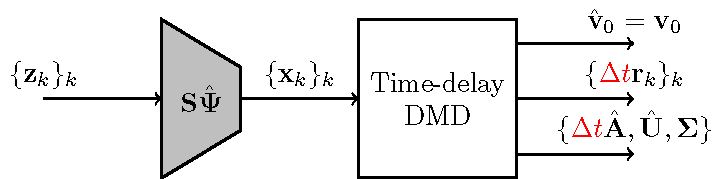

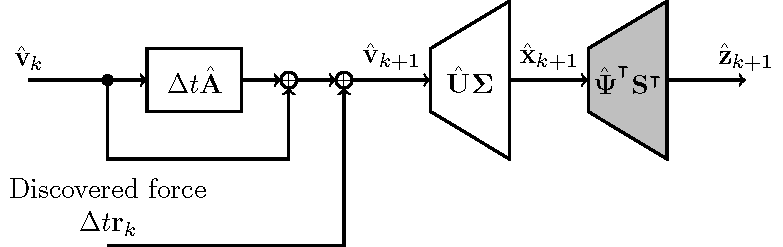

Parameters


$$\hat{\mathbf{v}}_0$$


v0hat

v0hat =    -0.0282
    0.0132
   -0.0309
   -0.0057
   -0.0323
    0.0197
    0.0366
   -0.0197
    0.0049
    0.0029



$$\{\Delta t \mathbf{r}_k\}$$


dtr

dtr =    -0.0000    0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.0001   -0.0001   -0.0002    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   


$$\mathbf{I}+\Delta t \hat{\mathbf{A}}$$


dtAplusI

dtAplusI =     0.9987   -0.0032   -0.0084   -0.0462    0.0047   -0.0040    0.0020   -0.0002   -0.0009   -0.0000   -0.0002    0.0001
    0.0028    0.9954    0.0852   -0.0193   -0.0541    0.0011    0.0032    0.0068    0.0005   -0.0016   -0.0009   -0.0010
    0.0065   -0.0906    0.9850   -0.0158   -0.1393   -0.0142   -0.0298    0.0271    0.0015   -0.0073    0.0012   -0.0044
    0.0462    0.0172    0.0149    0.9769   -0.0153    0.1774   -0.0914   -0.0149    0.0133    0.0027    0.0045    0.0007
   -0.0039    0.0427    0.1469    0.0155    0.9622   -0.0181    0.0272   -0.2090   -0.0105    0.0371   -0.0009    0.0186
   -0.0017   -0.0076    0.0108   -0.1788    0.0336    0.8858    0.0114    0.0624    0.1962    0.1633   -0.0059    0.0046
    0.0066   -0.0120    0.0218    0.0873   -0.0069    0.0646    0.9129    0.1553   -0.1615    0.2240   -0.1500    0.0194
   -0.0012    0.0069   -0.0004    0.0189    0.2141   -0.0746   -0.1045    0.8150    0.1081   -0.2480   -0.1605   -0.1528
    0.0011   -0.0009 


$$\hat{\mathbf{U}}$$


Uhat = U(1:nDim,:);
Uhat

Uhat =    -0.4958   -0.0659   -0.0172   -0.6685    0.0235    0.4381   -0.2395   -0.0338   -0.2040   -0.0723   -0.0694    0.0036
   -0.0440    0.3180   -0.4996   -0.0009   -0.0996   -0.2958   -0.5348    0.0308   -0.1153    0.4548   -0.0699   -0.1948
   -0.0430    0.3761    0.1208    0.0251    0.6957    0.0149   -0.0612    0.5338   -0.0798   -0.0133    0.2143    0.1270



$$\mathbf{\Sigma}$$


Sgm

Sgm = 1.0e+03 *

    2.1627         0         0         0         0         0         0         0         0         0         0         0
         0    0.9095         0         0         0         0         0         0         0         0         0         0
         0         0    0.2610         0         0         0         0         0         0         0         0         0
         0         0         0    0.1162         0         0         0         0         0         0         0         0
         0         0         0         0    0.0689         0         0         0         0         0         0         0
         0         0         0         0         0    0.0116         0         0         0         0         0         0
         0         0         0         0         0         0    0.0105         0         0         0         0         0
         0         0         0         0         0         0         0    0.0078         0         0         0         0
         0     

Step 5

vkhat = v0hat;
dtrk = dtr(:,1);
Xhat = (Uhat*Sgm*vkhat).';
for k = 1:nRange-nDelay
    dtrk = dtr(:,k);
    vkp1hat = dtAplusI*vkhat + dtrk;
    Xhat = cat(1,Xhat,(Uhat*Sgm*vkp1hat).');
    % Update
    vkhat = vkp1hat;
end

Visualize

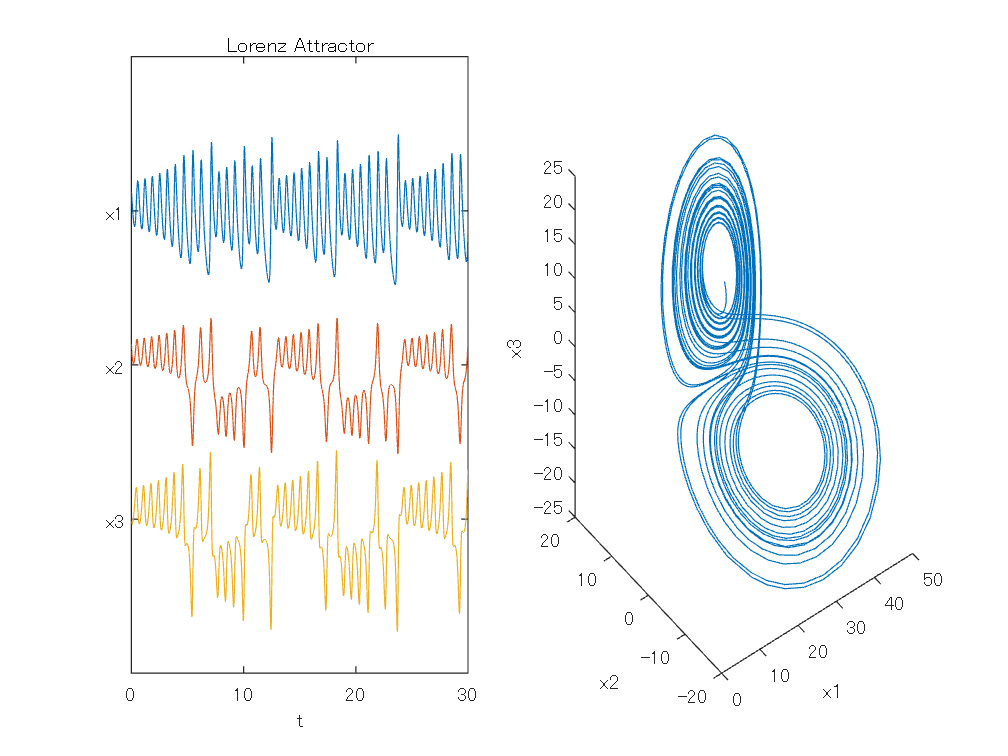

myplot(t(1:size(Xhat,1)),Xhat);

Post-processing w/ LSUN

function [t,y] = lorenzgen(params)

sigma = params.sigma;
beta = params.beta;
rho = params.rho;
eta = params.eta;

A = [ -beta 0 eta;
    0 -sigma sigma;
    -eta rho -1 ];
v0 = [rho-1 eta eta]';
y0 = v0 + [3 2 -4]';
tspan = [0 30];

[t,y] = ode45(@(t,y) lorenzeqn(t,y,A), tspan, y0);
end

function ydot = lorenzeqn(t,y,A)

A(1,3) = y(2);
A(3,1) = -y(2);
ydot = A*y;

end

function myplot(t,x)

subplot(1,2,1)
plot(t,[x(:,1)+15 x(:,2)-5 x(:,3)-45]);
axis([0 30 -80 80])
set(gca,'ytick',[-40 0 40],'yticklabel',{'x3','x2','x1'})
xlabel('t')
title('Lorenz Attractor')

subplot(1,2,2)
plot3(x(:,1),x(:,2),x(:,3));
xlabel('x1')
ylabel('x2')
zlabel('x3')

end